# Force Plate Calibration and Visualization Script

This MATLAB script give calibration and visualization of a force plate using marker data from Vicon motion capture system. Below is a detailed explanation of the code:

## 1. Force Plate Definition

%% DEFINE FORCE PLATE OBJECT
FPLenght = 600; % mm
FPwidth = 500; % mm
edgeBand = 40; % Width death zone mm (for marker position) 
UnitVecFactor = 100; % Scaling Factor (mm) of unitary Frame of Reference
MarkerHeight = 0; % Marker height base to centroid

## 2. Initial Rotation and Marker Positions

global MarkersVec EdgeVec unitVecX unitVecY unitVecZ MakersFromViconRotCalc ;
theta=pi;
ROT_init=[cos(theta) -sin(theta) 0;...
          sin(theta) cos(theta) 0;...
          0 0 1];
MarkersVec_1=[
    -FPwidth/2+edgeBand, FPwidth/2-edgeBand, -FPwidth/2+edgeBand;...
    FPLenght/2-edgeBand, FPLenght/2-edgeBand, -FPLenght/2+edgeBand;...
    MarkerHeight, MarkerHeight, MarkerHeight];
MarkersVec = ROT_init*MarkersVec_1;

Defines initial marker positions in a triangular configuration:

- Marker 1: Top-left corner

- Marker 2: Top-right corner

- Marker 3: Bottom-left corner

Positions are offset from edges by `edgeBand`

## 3. Edge and Unit Vector Definitions

EdgeVec = ...
    [FPwidth/2, -FPwidth/2 , -FPwidth/2,  FPwidth/2, FPwidth/2;...
    FPLenght/2, FPLenght/2, -FPLenght/2, -FPLenght/2,  FPLenght/2;...
    0, 0 , 0 , 0 , 0];

- Defines the force plate edges for visualization (a rectangle)

- The sequence creates a closed loop around the plate perimeter

unitVecX= [0, UnitVecFactor; 0 , 0 ; 0 , 0];
unitVecY= [0, 0; 0 , UnitVecFactor ; 0 , 0];
unitVecZ= [0, 0; 0 , 0 ; 0 , UnitVecFactor];

- Creates unit vectors for X, Y, Z axes (scaled by `UnitVecFactor`)

- Used to visualize the reference frame

## 4. Vicon Measurement Data Acquisition

vicon = ViconNexus();
Markers = vicon.GetMarkerNames('ForcePlate3Points');
n = length(Markers);

trajX = cell(1, n); trajY = cell(1, n); trajZ = cell(1, n);
for i = 1:n
 [trajX{i}, trajY{i}, trajZ{i}, ~] = vicon.GetTrajectory('ForcePlate3Points', Markers{i});
end

- Connects to Vicon Nexus software

- Retrieves marker names and trajectory data for three markers

- Stores X, Y, Z coordinates of each marker over time

## 5. Data Processing and Center Calculation

X = cellfun(@mean, trajX);
Y = cellfun(@mean, trajY);
Z = cellfun(@mean, trajZ);

M1 = [X(1); Y(1); Z(1)];
M2 = [X(2); Y(2); Z(2)];
M3 = [X(3); Y(3); Z(3)];

Center = (M2+M3)/2;
MakersFromViconRotCalc =[M1-Center,M2-Center,M3-Center];

- Calculates mean position of each marker

- Computes force plate center as midpoint between markers 2 and 3

## 6. Initial Visualization

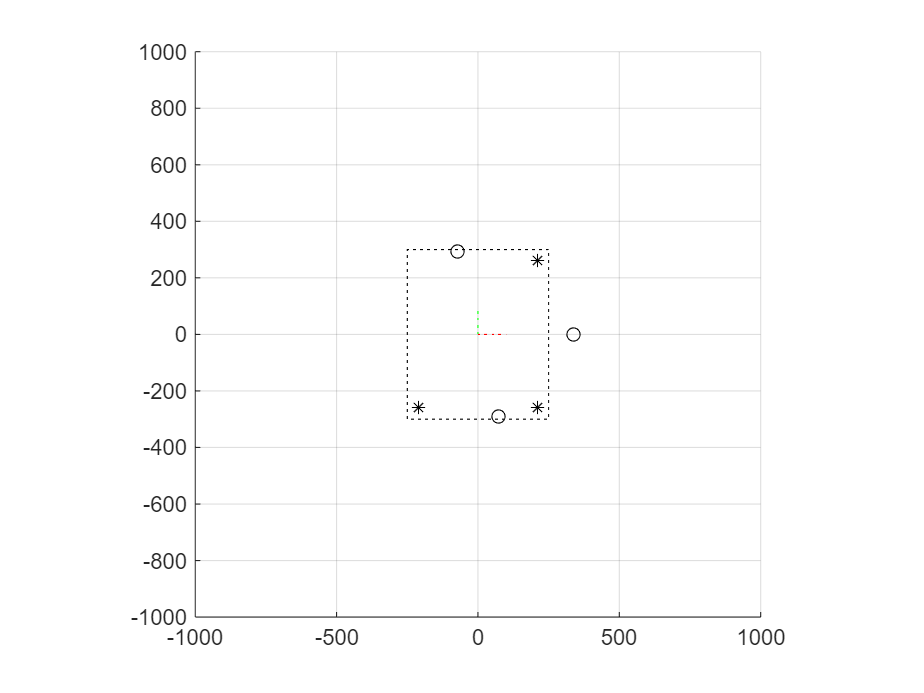

figure(1); hold on; axis equal; grid on;  xlim([-1000, 1000]); ylim([-1000, 1000])

plot3(EdgeVec(1,:), EdgeVec(2,:), EdgeVec(3,:),':k')
plot3(MarkersVec(1,:), MarkersVec(2,:), MarkersVec(3,:),'*k')
plot3(unitVecX(1,:), unitVecX(2,:), unitVecX(3,:),':r')
plot3(unitVecY(1,:), unitVecY(2,:), unitVecY(3,:),':g')
plot3(unitVecZ(1,:), unitVecZ(2,:), unitVecZ(3,:),':b')
plot3(MakersFromViconRotCalc(1,:), MakersFromViconRotCalc(2,:), MakersFromViconRotCalc (3,:),'ok')

Creates a 3D plot showing:

- Force plate edges

- Ideal marker positions

- Reference frame axes

- Actual measured marker positions

## 7. Optimization Process

global err 
err = [200];
Xub = [pi; pi; pi]; Xlb = -Xub; % Upper and lower bounds
X0 = [0; 0; 0];      % Innitial seed rotation 

while err(end) >=10
    OPTIONS = optimoptions('fmincon','Algorithm','SQP');  % alternatives : interior point, SQP,  active-set, and trust-region-reflective
    Xopt = fmincon(@objective, X0, [], [], [], [], Xlb, Xub, [], OPTIONS );  
    X0 = randn(3,1)*pi; % New seed for next iteration
end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu


Xopt_f=Xopt*180/pi;

- Uses constrained optimization (`fmincon`) to find the best rotation angles

- Objective function minimizes difference between ideal and measured marker positions

- Runs multiple iterations with random starting points until error < 10mm

- Uses Sequential Quadratic Programming (SQP) algorithm

## 8. Final Transformation and Visualization

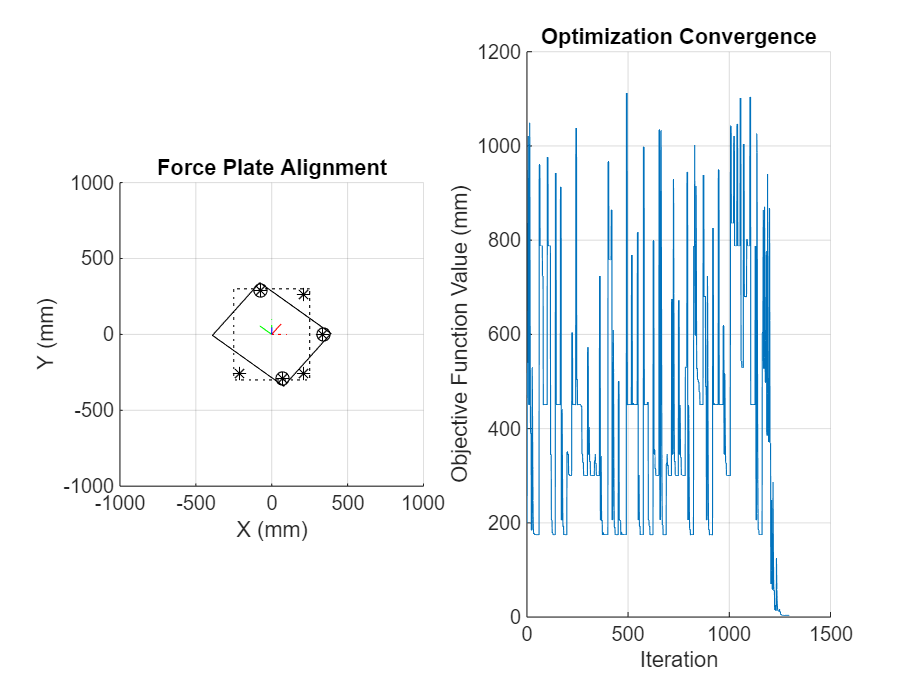

%% VISUALIZE
figure(1); clf;

subplot(1,2,1); 
hold on; axis equal; grid on;  
xlim([-1000, 1000]); ylim([-1000, 1000]);
xlabel('X (mm)'); ylabel('Y (mm)'); zlabel('Z (mm)');
title('Force Plate Alignment');

% Plot initial positions
plot3(EdgeVec(1,:), EdgeVec(2,:), EdgeVec(3,:),':k')
plot3(MarkersVec(1,:), MarkersVec(2,:), MarkersVec(3,:),'*k')
plot3(unitVecX(1,:), unitVecX(2,:), unitVecX(3,:),':r')
plot3(unitVecY(1,:), unitVecY(2,:), unitVecY(3,:),':g')
plot3(unitVecZ(1,:), unitVecZ(2,:), unitVecZ(3,:),':b')
plot3(MakersFromViconRotCalc(1,:), MakersFromViconRotCalc(2,:), MakersFromViconRotCalc(3,:),'ok') 

ROT = rotationMatrix(Xopt);
% Transform Object 
EdgeVec = ROT*EdgeVec;
MarkersVecFinal = ROT*MarkersVec;
unitVecX = ROT*unitVecX;
unitVecY= ROT*unitVecY;
unitVecZ = ROT*unitVecZ;

plot3(EdgeVec(1,:), EdgeVec(2,:), EdgeVec(3,:),'-k')
plot3(MarkersVecFinal(1,:), MarkersVecFinal(2,:), MarkersVecFinal(3,:),'*k')
plot3(unitVecX(1,:), unitVecX(2,:), unitVecX(3,:),'-r')
plot3(unitVecY(1,:), unitVecY(2,:), unitVecY(3,:),'-g')
plot3(unitVecZ(1,:), unitVecZ(2,:), unitVecZ(3,:),'-b')

subplot(1,2,2); 
hold on; grid on;
plot(err, 'LineWidth', 0.5);
ylabel('Objective Function Value (mm)');
xlabel('Iteration');
title('Optimization Convergence');

Applies the optimized rotation to:

- Force plate edges

- Marker positions

- Reference frame axes

## 9. Results Output

d12 = norm([X(2)-X(1), Y(2)-Y(1), Z(2)-Z(1)]);
d13 = norm([X(3)-X(1), Y(3)-Y(1), Z(3)-Z(1)]);
dim_x = d12 + 2*38.25;
dim_y = d13 + 2*38.25;

filename = 'FP_parameters.txt';
fid = fopen(filename, 'w');
fprintf(fid, 'FP Parameters\n-----------------------------\n');
fprintf(fid, 'Force plate dimensions (in mm):\n');
fprintf(fid, '-Length X: %.2f mm\n-Width Y: %.2f mm\n\n', dim_x, dim_y);
fprintf(fid, 'Center position (in mm):\n');
fprintf(fid, '-X: %.2f mm\n-Y: %.2f mm\n-Z: %.2f mm\n\n', Center(1), Center(2), Center(3));
fprintf(fid, 'Orientation (in degrees):\n');
fprintf(fid, '-Angle X: %.2f°\n-Angle Y: %.2f°\n-Angle Z: %.2f°\n\n', Xopt_f(1), Xopt_f(2), Xopt_f(3));
fclose(fid);

Calculates force plate dimensions from marker distances

Writes all parameters to a text file:

- Dimensions

- Center position

- Orientation angles

## 10. Supporting Functions

### Objective Function

function obj = objective(X1)
    ROT1 = rotationMatrix(X1);
    global MarkersVec  
    global MakersFromViconRotCalc
    global err
    MarkersVec0 = ROT1*MarkersVec;
    obj = sqrt(sum(sum((MarkersVec0-MakersFromViconRotCalc).^2)));
    err = [err, obj];
end

- Computes RMS error between rotated ideal markers and measured markers

- Tracks error history in global variable `err`

### Rotation Matrix Function

function ROT2 = rotationMatrix(X2)
   % X2=deg2rad(X);
    steps = 100;             % X2 is divided into steps to approximate the rotation X2 is in Radians
    X2 = X2/steps;
    ROT2 = eye(3);
    for i = 1 : steps
        rotX = [ 1, 0, 0; 0, cos(X2(1)), -sin(X2(1)); 0, sin(X2(1)), cos(X2(1))]; 
        rotY = [cos(X2(2)),0 ,sin(X2(2)); 0, 1, 0 ; -sin(X2(2)), 0, cos(X2(2))]; 
        rotZ = [cos(X2(3)), -sin(X2(3)),0 ; sin(X2(3)), cos(X2(3)), 0 ; 0, 0, 1 ]; 
        ROT2 = rotZ*rotY*rotX*ROT2;
    end
end

- Computes composite rotation matrix from Euler angles

- Applies rotation in small steps for better numerical stability

- Combines rotations around X, Y, and Z axes